===============================================================================

# Pràctica 8. Derivació Numèrica

## 1. Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab8.pdf i en el document CN_full7.pdf, els podeu trobar en el campus virtual. 

### MATLAB®  -  Derivació numèrica

Use the `diff` function to approximate partial derivatives with the syntax `Y = diff(f)/h`, where `f` is a vector of function values evaluated over some domain, `X`, and `h` is an appropriate step size.

For example, the first derivative of `sin(x)` with respect to `x` is `cos(x)`, and the second derivative with respect to `x` is `-sin(x)`. You can use `diff` to approximate these derivatives.

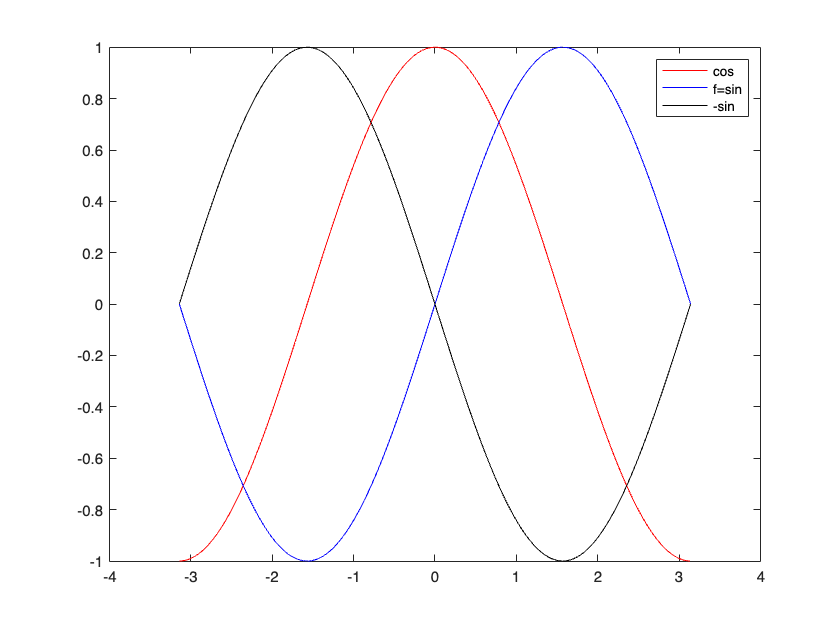

h = 0.001;       % step size
X = -pi:h:pi;    % domain
f = sin(X);      % range
Y = diff(f)/h;   % first derivative
Z = diff(Y)/h;   % second derivative
plot(X(:,1:length(Y)),Y,'r',X,f,'b', X(:,1:length(Z)),Z,'k'),legend('cos','f=sin','-sin')

In this plot the blue line corresponds to the original function, `sin`. The red line corresponds to the calculated first derivative, `cos`, and the black line corresponds to the calculated second derivative, `-sin`.

*Copyright 2015 The MathWorks, Inc.*

### MATLAB®  - Vector gradient

Calculate the 2-D gradient of $x e^{-x^2-y^2}$ on a grid.

x = -2:0.2:2;
y = x';
z = x .* exp(-x.^2 - y.^2);
[px,py] = gradient(z);

Plot the contour lines and vectors in the same figure.

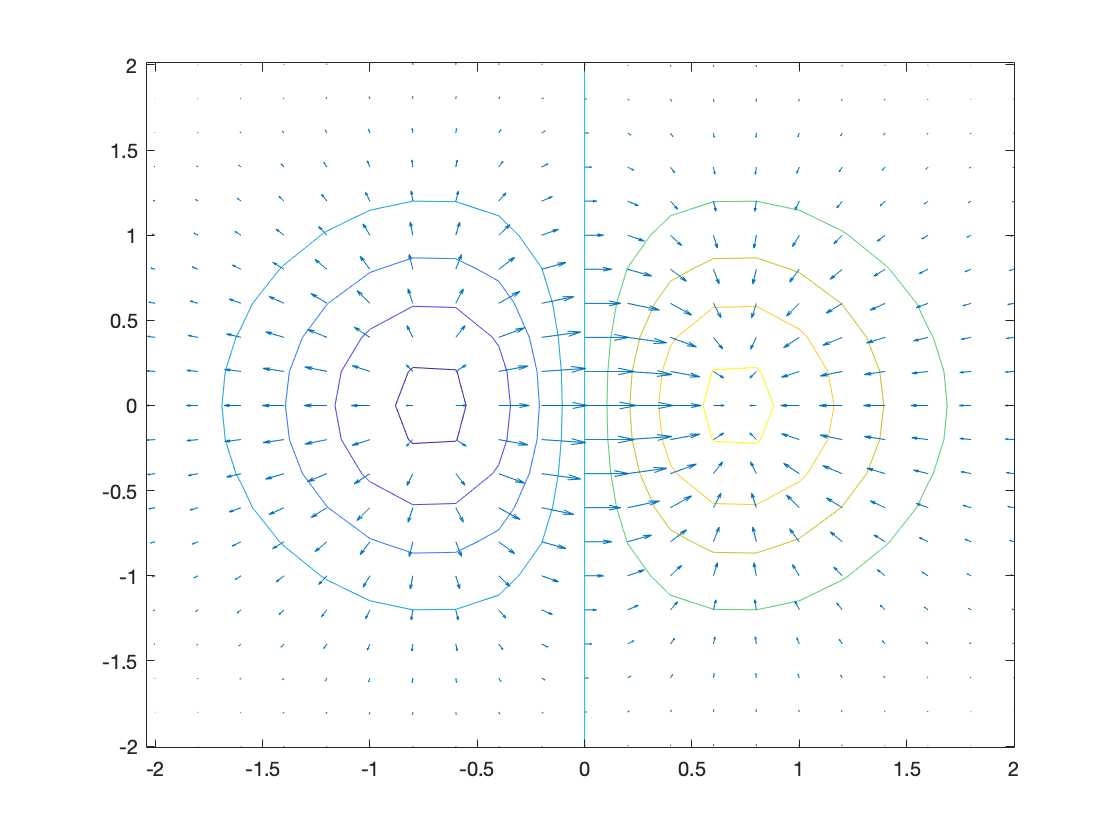

figure
contour(x,y,z)
hold on
quiver(x,y,px,py)
hold off

*Copyright 2012 The MathWorks, Inc.*

## 2. Aprenem... Fòrmules bàsiques.

### Exercici 1. 

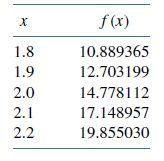

Calcular f'(2.0) con h=0.1 y h=02. Los datos son de f(x)=x*e^x, calcular los errores absolutos. Crear tabla para visualitzar error absoluto en las fórmulas usadas

clearvars
x=[1.8:0.1:2.2] 

x =           1.8          1.9            2          2.1          2.2


y=[x.*exp(x)]

y =        10.889       12.703       14.778       17.149       19.855


disp([x;y]')

          1.8       10.889
          1.9       12.703
            2       14.778
          2.1       17.149
          2.2       19.855



% valor exacte
valor =(x(3)+1)*exp(x(3))

valor =        22.167


% formula centrada h=0.2
yp1 = (y(5)-y(1))/(2*0.2); 
R = [valor,yp1,abs(yp1-valor),abs(yp1-valor)/valor]

R =        22.167       22.414      0.24699     0.011142



% formula centrada h=0.1
yp2 = (y(4)-y(2))/(2*0.1)

yp2 =        22.229


R = [R;valor,yp2,abs(yp2-valor),abs(yp2-valor)/valor]

R =        22.167       22.414      0.24699     0.011142
       22.167       22.229     0.061619    0.0027797


% taula resultats
format short g;
rowNames = {'h=0.2','h=0.1'};
varNames = {'y´(2)','valor aproximat','error absolut','error relatiu'}; 
T = array2table(R,'RowNames',rowNames,'VariableNames',varNames); 
disp(T)

             y´(2)     valor aproximat    error absolut    error relatiu
             ______    _______________    _____________    _____________

    h=0.2    22.167        22.414            0.24699          0.011142  
    h=0.1    22.167        22.229           0.061619         0.0027797  



### Exercici 2 

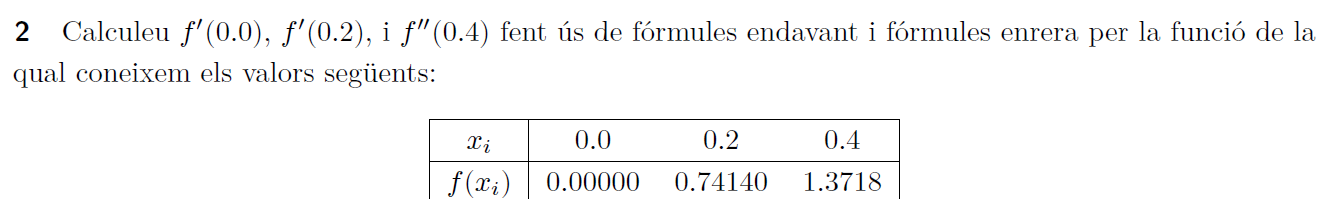

clearvars
x=[0 0.2 0.4]; 
y=[0 0.74140 1.3718]; 

% formula endavant h=0.2
yp(1) = (y(2)-y(1))/(0.2)  % f'(0) 

yp =         3.707


yp(2) = (y(3)-y(2))/(0.2)  % f'(0.2) endavant

yp =         3.707        3.152


yp(3) = NaN  % f'(0.4) endavant

yp =         3.707        3.152          NaN



format short g;
varNames = {'method','y´(0)','y´(0.2)','y´(0.4)'}; 
T=table(categorical({'forward'}),yp(1),yp(2),yp(3),'VariableNames',varNames);
disp(T)

    method     y´(0)    y´(0.2)    y´(0.4)
    _______    _____    _______    _______

    forward    3.707     3.152       NaN  





% formula enrera h=0.2
yp(1) = NaN;  % f'(0) enrera
yp(2) = (y(2)-y(1))/(0.2);  % f'(0.2) enrera
yp(3) = (y(3)-y(2))/(0.2);  % f'(0.4) enrera
format short g;
varNames = {'method','y´(0)','y´(0.2)','y´(0.4)'}; 
T=table(categorical({'backward'}),yp(1),yp(2),yp(3),'VariableNames',varNames);
disp(T)

     method     y´(0)    y´(0.2)    y´(0.4)
    ________    _____    _______    _______

    backward     NaN      3.707      3.152 



### Exercici 3

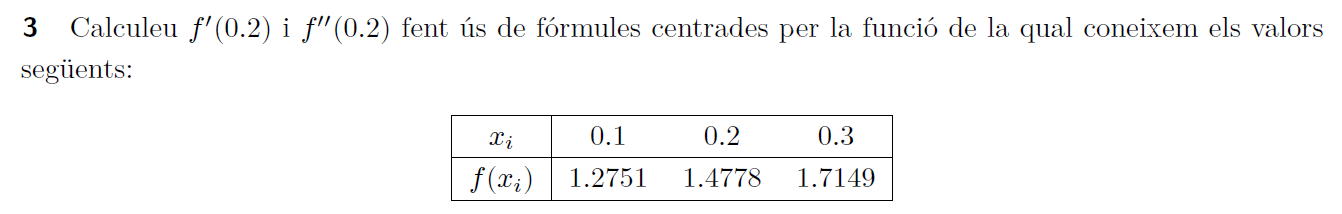

clearvars
x=[0.1, 0.2,0.3];  %diferències entre xi - x(i-1) = pas de derivació 
y=[1.2751 1.4778 1.7149]; 

h = x(2)-x(1);
yp = (y(3)-y(1))/(2*h)             % f'(0.2) centrada derivada primera

yp =         2.199


ypp = (y(3)-2*y(2)+y(1))/(h^2)     % f''(0.2) centrada derivada segona (formulilla pg 14 teoria derivacio)

ypp =          3.44


rowNames = {' y´(0.2)','y´´(0.2)'};
varNames = {'valor aproximat'}; 
R = [yp;ypp];
T = array2table(R,'RowNames',rowNames,'VariableNames',varNames)

T = 2×1 table
                valor aproximat
                _______________

    y´(0.2)          2.199     
    y´´(0.2)          3.44     


disp(T)

                valor aproximat
                _______________

    y´(0.2)          2.199     
    y´´(0.2)          3.44     



### **Exercici 4**

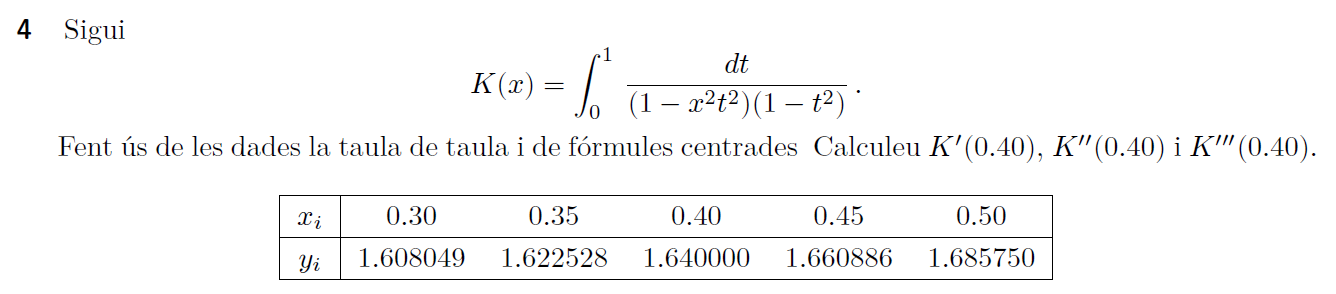

clearvars
x=[0.3:0.05:0.5];
x2=x .^2;
format longG
y = round(ellipke(x2),7,'significant');
T = array2table([x;y]',"VariableNames",{'x_i','y_i'}); disp(T)

    x_i       y_i   
    ____    ________

     0.3    1.608049
    0.35    1.622528
     0.4        1.64
    0.45    1.660886
     0.5     1.68575



h = x(2)-x(1);
yp = (y(4)-y(2))/(2*h);                       % K'(0.40) centrada derivada primera
ypp = (y(4)-2*y(3)+y(2))/(h^2);               % K''(0.40) centrada derivada segona
yppp = (y(5)-2*y(4)+2*y(2)-y(1))/(8*h^3);     % K''(0.40) centrada derivada TERCERA
rowNames = {'K´(0.4)','K´´(0.4)','K´´´(0.4)'};
varNames = {'valor aproximat'}; 
R = [yp;ypp;yppp];
T = array2table(R,'RowNames',rowNames,'VariableNames',varNames);
disp(T)

                  valor aproximat 
                 _________________

    K´(0.4)      0.383580000000001
    K´´(0.4)       1.3656000000001
    K´´´(0.4)    0.984999999999792



## 3. Practiquem...  

### **Exercici 5  **O(h)

Se sabe que la derivada de $\ln(x)$ en $x=2$ tiene el valor de $f^{\prime}(2)=\frac 12$. Se pide:

a) Aproximar $f^{\prime}(2)$ mediante la fórmula $	\mathbf{F1}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0)}{h}
$, per $h_k=5^{-k}$ para $k=1,2,3\dots, 15.$

%fórmula endavant
clearvars
format longG
f = @(x)log(x);
k=0:30;
h=1./2.^k;
fp = (f(2+h)-f(2))./h;

% table = zeros(15, 3);
% for k=1:15
%     table(k, 1) = k;
%     table(k, 2) = (func(2+hfunc(k)) - func(2))/(hfunc(k));
%     table(k, 3) = abs(table(k, 2) - 0.5);
% % end
% T = array2table(table,'VariableNames', {'Iteracio', 'Valor', 'Error Absolut'});
% disp(T)

b) Calculad el error absolut opara cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla T2.  Representad el error en una gráfica, absicisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$

er = abs(fp-0.5);
taula=[h; fp; er]'

taula =                          1         0.405465108108164        0.0945348918918357
                       0.5          0.44628710262842        0.0537128973715804
                      0.25         0.471132142625534        0.0288678573744661
                     0.125         0.484996974531479        0.0150030254685207
                    0.0625         0.492346538668059         0.007653461331941
                   0.03125          0.49613396915089        0.0038660308491103
                  0.015625         0.498056988291516       0.00194301170848377
                 0.0078125         0.499025973204141      0.000974026795859118
                0.00390625         0.499512353603023      0.000487646396976515
               0.001953125          0.49975601820438       0.00024398179562013


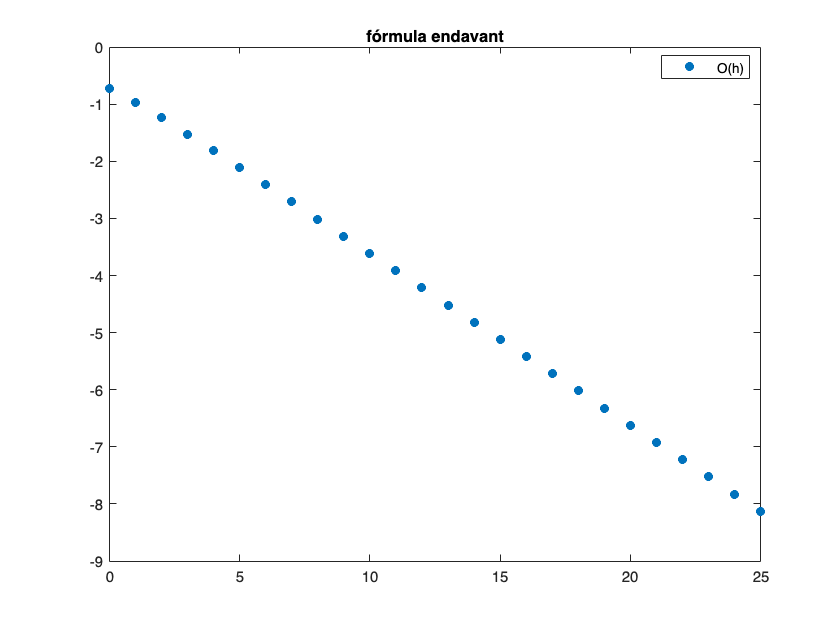

plot(k,log10(2*er),'*','LineWidth',2),legend('O(h)','Location','best'),title('fórmula endavant')

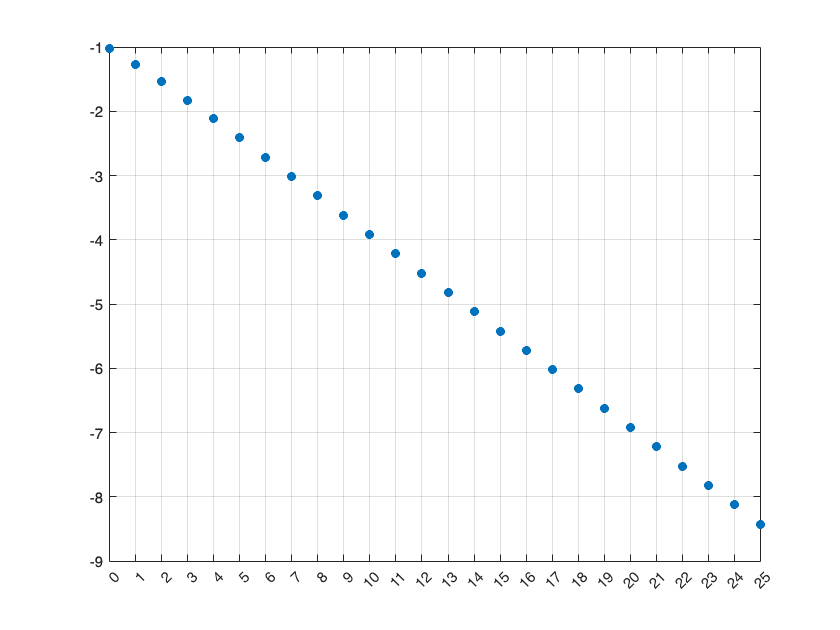


% plot(table(:, 1), log10(table(:, 2)))
plot(k,log10(er),'*','LineWidth',2),xticks(k),grid

**c) **Observad la existencia de un h óptimo, a partir del cúal si se toman valores de $h$ más pequeños, los errores crecen. Cúal es el valor de h para la fórmula $\mathbf{F1}$?

**RESPUESTA:: **

### **Exercici 6  **O(h^2)

Repetir el ejercicio 5 usando la fórmula $\mathbf{F2}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0-h)}{2h}.$

% Fórmula centrada
clearvars
f=@(x)log(x);
k=0:15;
h=1./2.^k;
% for k=1:15
%     fp2(k)=(f(2+h(k))-f(2-h(k)))/(2*h(k));
% end
fp2 = (f(2+h)-f(2-h))./(2*h);

**b)** Calculad el error absoluto para cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla.

Representad el error en una gráfica, abscisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$

er2 = abs(fp2-0.5);
taula=[h; fp2; er2]'

taula =                          1         0.549306144334055        0.0493061443340548
                       0.5         0.510825623765991        0.0108256237659907
                      0.25         0.502628856561812       0.00262885656181222
                     0.125         0.500652571816024      0.000652571816024405
                    0.0625         0.500162855850672      0.000162855850671662
                   0.03125         0.500040696065671      4.06960656711419e-05
                  0.015625         0.500010172898588      1.01728985875127e-05
                 0.0078125         0.500002543154793      2.54315479253364e-06
                0.00390625         0.500000635784332      6.35784331848299e-07
               0.001953125         0.500000158945795      1.58945795192267e-07


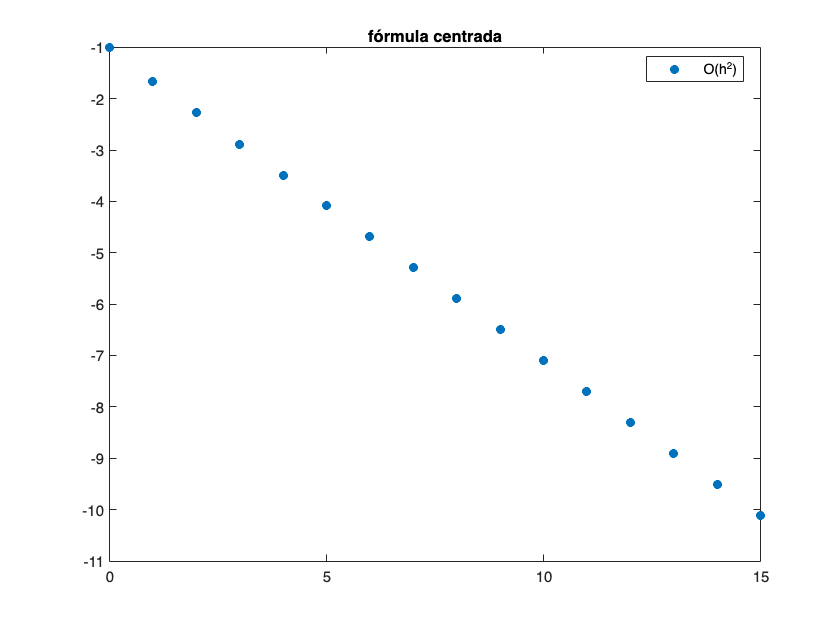

% Gràficament

plot(k,log10(2*er2),'*','LineWidth',2),legend('O(h^2)','Location','best'),title('fórmula centrada')

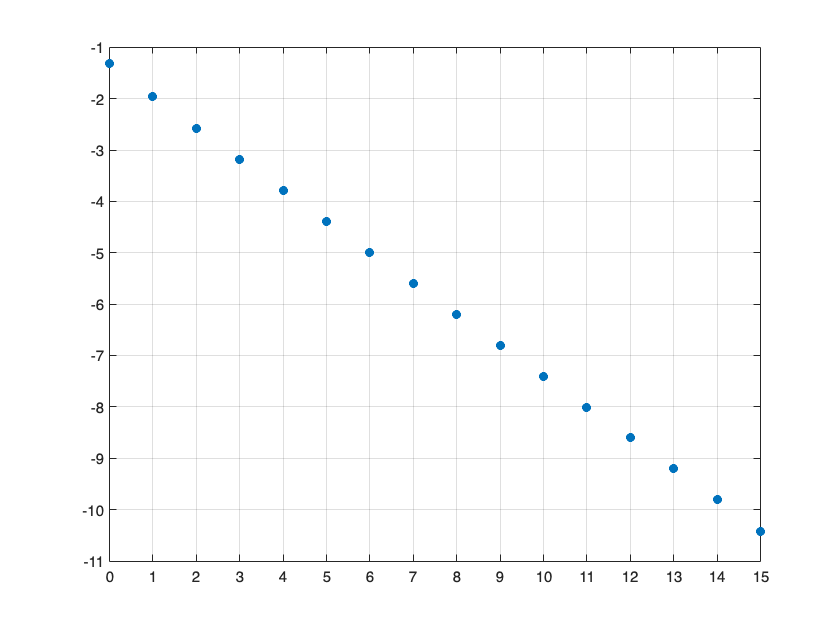

plot(k,log10(er2),'*','LineWidth',2),xticks(k),grid

**c) **Observad la existencia de un h óptimo, a partir del cúal si se toman valores de $h$ más pequeños, los errores crecen. 

Cúal es el valor de h para la fórmula $\mathbf{F2}$?

**RESPUESTA:: **

## 4. Practiquem...  

### **Exercici 7  **O(h^2)

Se sabe que la derivada de $\ln(x)$ en $x=2$ tiene el valor de $f^{\prime}(2)=\frac 12$. Se pide:

a) Aproximar $f^{\prime}(2)$ mediante la fórmula $\mathbf{F2}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0-h)}{2h},$ per $h_k=2^{-k}$ para $k=1,2,3\dots, 15.$

clearvars
format shortG
f=@(x)log(x); 
punt=2; 
valorEsperat = 1/2; 
n = 15; 

hk = 1:n;
h(1:n) = 1 ./2.^hk;

%% Fórmula centrada per la primera derivada, N_1
%  taula mostra, h, el valor aprox i l'error absolut
for k=1:n
    fp(k) = (f(punt+h(k))-f(punt-h(k)))/(2*h(k));
end

er = abs(fp-valorEsperat);
taula = [h(1:n);fp;er]';
varNames = {'1/2^k','f´(2)','error'};
T = array2table(taula,'VariableNames',varNames); disp(T)

      1/2^k        f´(2)       error   
    __________    _______    __________

           0.5    0.51083      0.010826
          0.25    0.50263     0.0026289
         0.125    0.50065    0.00065257
        0.0625    0.50016    0.00016286
       0.03125    0.50004    4.0696e-05
      0.015625    0.50001    1.0173e-05
     0.0078125        0.5    2.5432e-06
     0.0039062        0.5    6.3578e-07
     0.0019531        0.5    1.5895e-07
    0.00097656        0.5    3.9736e-08
    0.00048828        0.5    9.9341e-09
    0.00024414        0.5    2.4836e-09
    0.00012207        0.5    6.2073e-10
    6.1035e-05        0.5    1.5552e-10
    3.0518e-05        0.5    3.8199e-11



b) Usad la técnica de Extrapolación de Richardson para obtener $f^{\prime}(2)$ con más decimales correctes. Calculad el error absolut opara cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla T3. Representad el error en una gráfica, absicisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$.

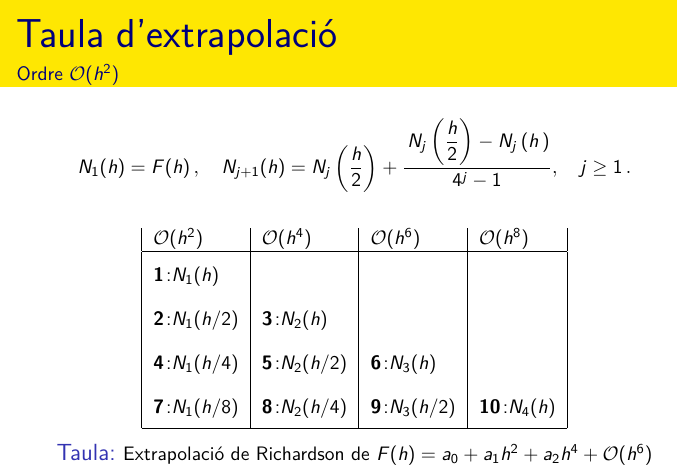

**Primera columna N_1**

disp(T)

      1/2^k        f´(2)       error   
    __________    _______    __________

           0.5    0.51083      0.010826
          0.25    0.50263     0.0026289
         0.125    0.50065    0.00065257
        0.0625    0.50016    0.00016286
       0.03125    0.50004    4.0696e-05
      0.015625    0.50001    1.0173e-05
     0.0078125        0.5    2.5432e-06
     0.0039062        0.5    6.3578e-07
     0.0019531        0.5    1.5895e-07
    0.00097656        0.5    3.9736e-08
    0.00048828        0.5    9.9341e-09
    0.00024414        0.5    2.4836e-09
    0.00012207        0.5    6.2073e-10
    6.1035e-05        0.5    1.5552e-10
    3.0518e-05        0.5    3.8199e-11



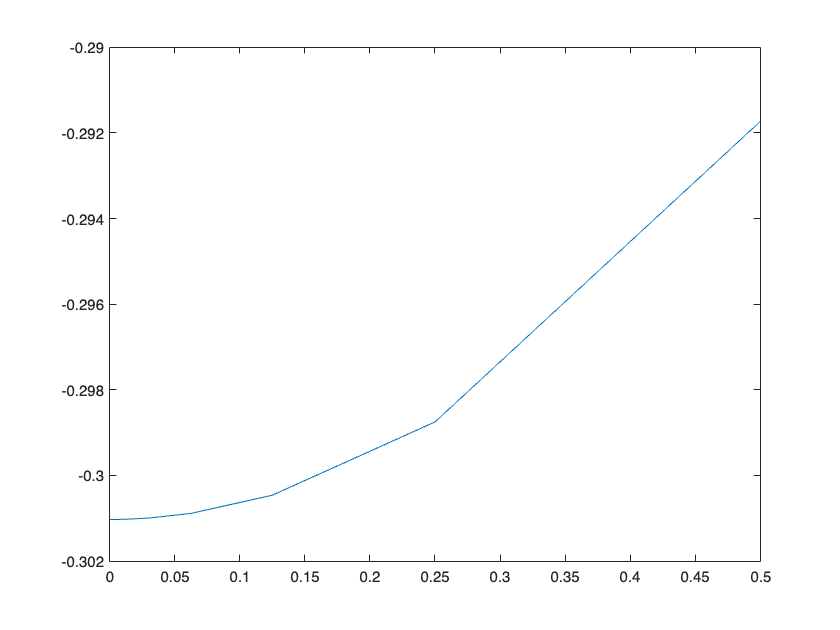

plot(taula(:, 1), log10(taula(:, 2)))

**Primera extrapolació, columna N_2**

T1(1) = 0;
T1(2:n) = (4*fp(2:n)-fp(1:n-1))/3;
er2 = abs(T1-valorEsperat); er2(1) = 0;
taula1 = [h(1:n);fp;T1;er2]';
varNames = {'1/2^k','N_1 = f´(2)','N_2 = f´(2)','error'};
T = array2table(taula1,'VariableNames',varNames); disp(T)

      1/2^k       N_1 = f´(2)    N_2 = f´(2)      error   
    __________    ___________    ___________    __________

           0.5      0.51083              0               0
          0.25      0.50263         0.4999       0.0001034
         0.125      0.50065        0.49999      6.1898e-06
        0.0625      0.50016            0.5       3.828e-07
       0.03125      0.50004            0.5      2.3863e-08
      0.015625      0.50001            0.5      1.4904e-09
     0.0078125          0.5            0.5      9.3139e-11
     0.0039062          0.5            0.5      5.8217e-12
     0.0019531          0.5            0.5      3.8369e-13
    0.00097656          0.5            0.5               0
    0.00048828          0.5            0.5      5.6843e-14
    0.00024414          0.5            0.5      1.1369e-13
    0.00012207          0.5          

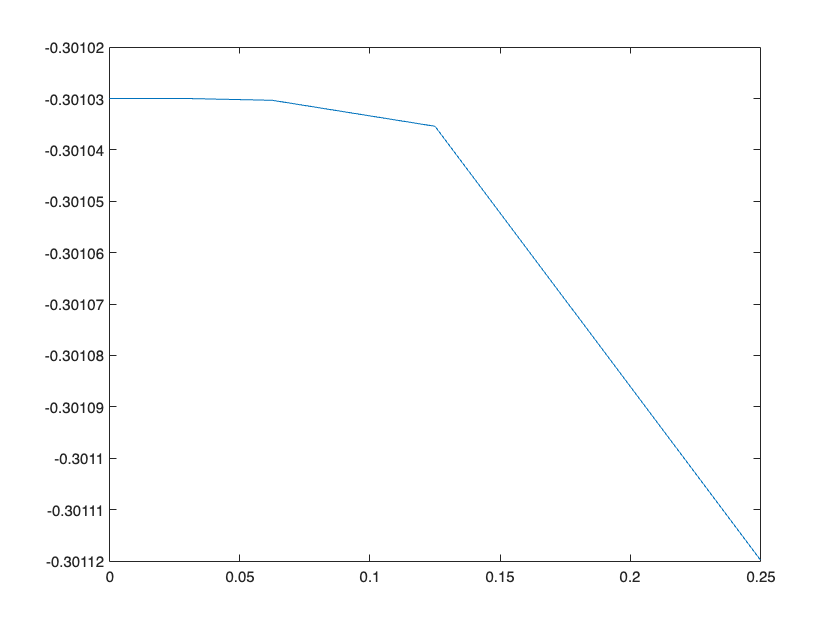

plot(taula1(:, 1), log10(taula1(:, 3)))

**Segona extrapolació, columna N_3**

T2(1:2) = 0;
T2(3:n) = (4^2*T1(3:n)-T1(2:n-1))/(4^2-1);
er3 = abs(T2-valorEsperat); er3(1:2) = 0;
taula2 = [h(1:n);fp;T1;T2;er3]';
varNames = {'1/2^k','N_1 = f´(2)','N_2 = f´(2)','N_3 = f´(2)','error'};
T = array2table(taula2,'VariableNames',varNames); disp(T)

      1/2^k       N_1 = f´(2)    N_2 = f´(2)    N_3 = f´(2)      error   
    __________    ___________    ___________    ___________    __________

           0.5      0.51083              0            0                 0
          0.25      0.50263         0.4999            0                 0
         0.125      0.50065        0.49999          0.5        2.9086e-07
        0.0625      0.50016            0.5          0.5        4.3263e-09
       0.03125      0.50004            0.5          0.5         6.679e-11
      0.015625      0.50001            0.5          0.5        1.0411e-12
     0.0078125          0.5            0.5          0.5        1.4322e-14
     0.0039062          0.5            0.5          0.5        6.1062e-16
     0.0019531          0.5            0.5          0.5         2.115e-14
    0.00097656 

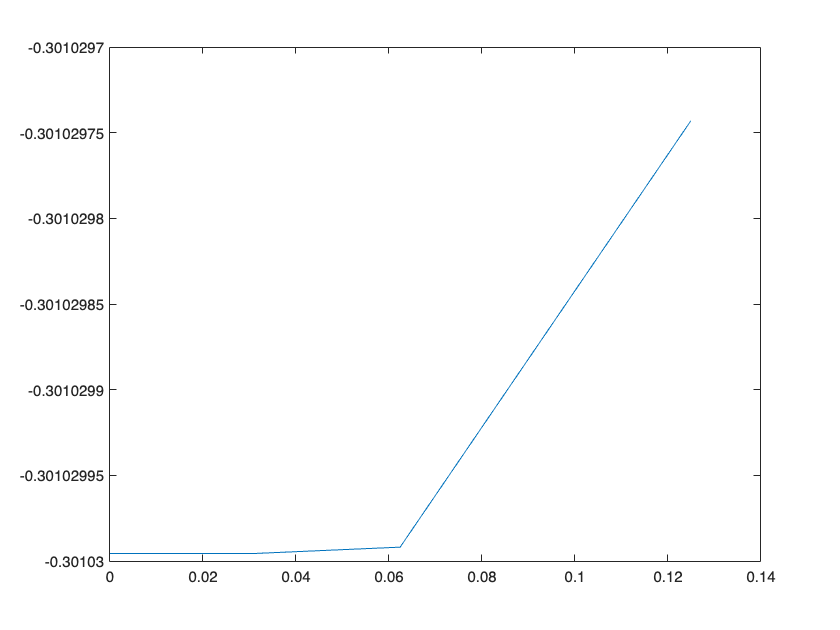

plot(taula2(:, 1), log10(taula2(:, 4)))

**Tercera extrapolació, columna N_4**

T3(1:3) = 0;
T3(4:n) = (4^3*T2(4:n)-T2(3:n-1))/(4^3-1);
er4 = abs(T3-valorEsperat); er4(1:3) = 0;
taula2 = [h(1:n);fp;T1;T2;T3;er4]';
varNames = {'1/2^k','N_1 = f´(2)','N_2 = f´(2)','N_3 = f´(2)','N_4 = f´(2)','error'};
T = array2table(taula2,'VariableNames',varNames); disp(T)

      1/2^k       N_1 = f´(2)    N_2 = f´(2)    N_3 = f´(2)    N_4 = f´(2)      error   
    __________    ___________    ___________    ___________    ___________    __________

           0.5      0.51083              0            0              0                 0
          0.25      0.50263         0.4999            0              0                 0
         0.125      0.50065        0.49999          0.5              0                 0
        0.0625      0.50016            0.5          0.5            0.5        2.2186e-10
       0.03125      0.50004            0.5          0.5            0.5        8.2162e-13
      0.015625      0.50001            0.5          0.5            0.5         2.609e-15
     0.0078125          0.5            0.5          0.5            0.5        1.998

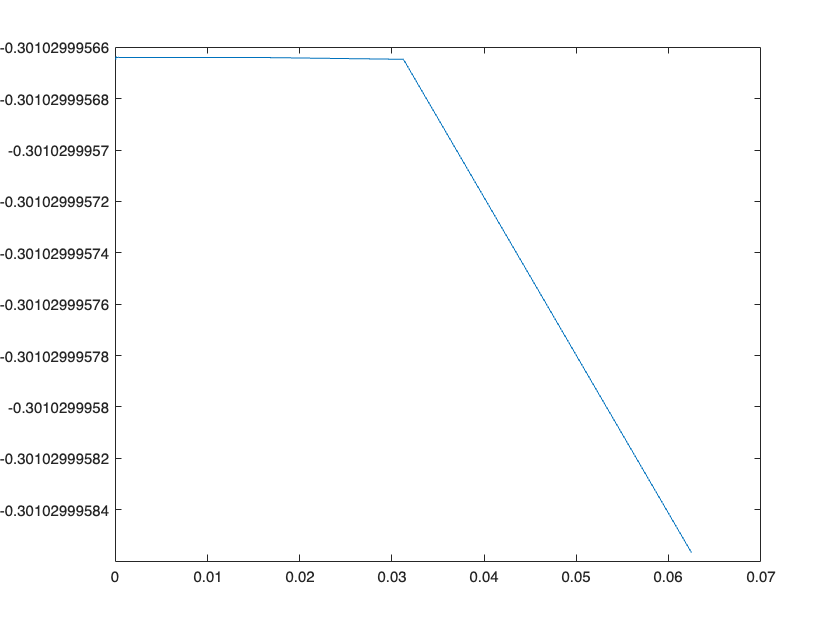

plot(taula2(:, 1), log10(taula2(:, 5)))

c) Representad las cifras decimales correctas en una gráfica con $k=1,2,3\dots, 15$ en el eje de abscisas.

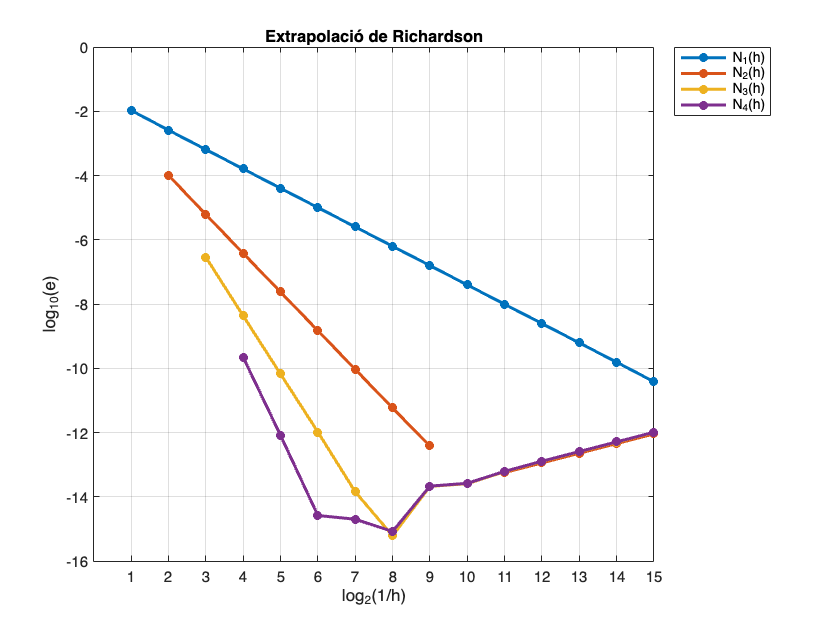

%% Gràfic
figure(1)
plot(hk,(log10(er)),'-*',hk,(log10(er2)),'-*',hk,(log10(er3)),'-*',hk,(log10(er4)),'-*','Linewidth',2); 
grid;
xlabel('log_{2}(1/h)');ylabel('log_{10}(e)'); title('Extrapolació de Richardson')
legend('N_1(h)','N_2(h)','N_3(h)','N_4(h)','Location','bestoutside'),xticks([1:n])

## 5. AutoAvaluació 

### Exercici 8

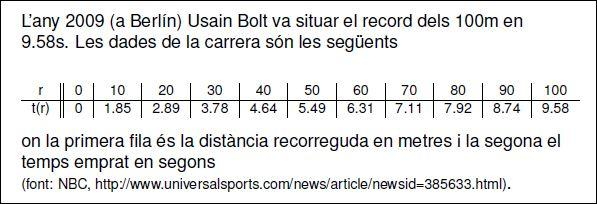

Calculeu una aproximació de la velocitat i l'acceleració en la carrera. Feu una representació gràfica 

dels valors obtinguts

format short g
r=0:10:100;
t=[0 1.85 2.89 3.78 4.64 5.49 6.31 7.11 7.92 8.74 9.58];
disp([r;t]')

**Velocitat i acceleració**

k=length(r);
v(1:11)=0; a(1:11)=0;
for i=2:11
    v(i)=(r(i)-r(i-1))/(t(i)-t(i-1));
    a(i)=(v(i)-v(i-1))/(t(i)-t(i-1));
end
taula=[r;t;v;a]'

**Gràfics**

xx = 0:1:100;
rr = spline(r,t,xx);
subplot(2,2,[1,2]),plot(r,t,'o',xx,rr)
xlabel('m');ylabel('temps (s)');
title('distància')
vv = spline(r,v,xx);
subplot(2,2,3),plot(r,v,'o',xx,vv)
xlabel('m');ylabel('v(t)');
title('velocitat'),xticks([0,20,40,60,80,100])
aa = spline(r,a,xx);
subplot(2,2,4),plot(r,a,'o',xx,aa)
xlabel('m');ylabel('a(t)');
title('acceleració'),xticks([0,20,40,60,80,100])

### Exercici 9.  O(h)

Se sabe que la derivada de $\ln(x)$ en $x=2$ tiene el valor de $f^{\prime}(2)=\frac 12$. Se pide:

a) Aproximar $f^{\prime}(2)$ mediante la fórmula $	\mathbf{F1}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0)}{h}
$, per $h_k=2^{-k}$ para $k=1,2,3\dots, 15.$

clearvars; 
format short g
f=@(x)atan(x); 
a=sqrt(2); ve=1/3; n = 15; hk = 1:n;
h(1:n) = 1 ./2.^hk;
% Fórmula centrada per la primera derivada, N_1
% for k=1:15
%     fp(k)=(f(a+h(k))-f(a))/h(k);
% end
fp = (f(a+h)-f(a))./h;
%  taula mostra, h, el valor aprox i l'error absolut
er = abs(fp-ve);
taula = [h(1:n);fp;er]';
varNames = {'1/2^k','f´(2)','error'};
T = array2table(taula,'VariableNames',varNames); disp(T)

      1/2^k        f´(2)       error   
    __________    _______    __________

           0.5    0.26813      0.065199
          0.25    0.29764      0.035693
         0.125    0.31462      0.018711
        0.0625    0.32375      0.009584
       0.03125    0.32848     0.0048507
      0.015625    0.33089     0.0024402
     0.0078125    0.33211     0.0012239
     0.0039062    0.33272    0.00061287
     0.0019531    0.33303    0.00030667
    0.00097656    0.33318    0.00015339
    0.00048828    0.33326    7.6711e-05
    0.00024414    0.33329    3.8359e-05
    0.00012207    0.33331    1.9181e-05
    6.1035e-05    0.33332    9.5905e-06
    3.0518e-05    0.33333    4.7953e-06



b) Usad la técnica de Extrapolación de Richardson para obtener $f^{\prime}(2)$ con más decimales correctes. Calculad el error absoluto  para cada una de las aproximaciones obtenidas. Presentar los resultados en una tabla T. Representad el error en una gráfica, absicisas $k=1,2,3\dots, 15$ y ordenadas $log_{10}(error)$.

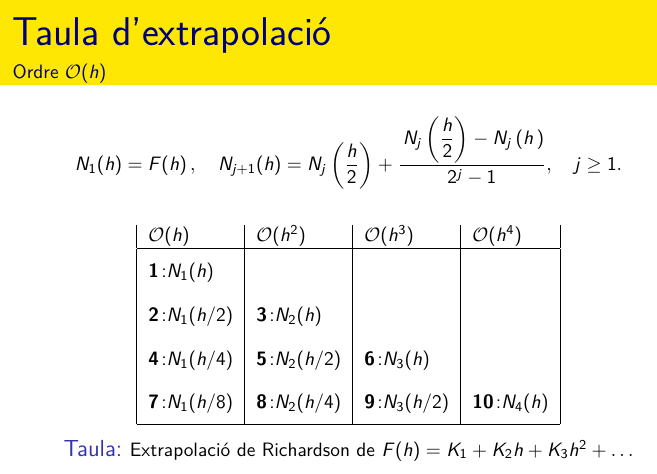

**Primera columna N_1**

varNames = {'1/2^k','N_1 = f´(2)','error'};
T = array2table(taula,'VariableNames',varNames); disp(T)

      1/2^k       N_1 = f´(2)      error   
    __________    ___________    __________

           0.5      0.26813        0.065199
          0.25      0.29764        0.035693
         0.125      0.31462        0.018711
        0.0625      0.32375        0.009584
       0.03125      0.32848       0.0048507
      0.015625      0.33089       0.0024402
     0.0078125      0.33211       0.0012239
     0.0039062      0.33272      0.00061287
     0.0019531      0.33303      0.00030667
    0.00097656      0.33318      0.00015339
    0.00048828      0.33326      7.6711e-05
    0.00024414      0.33329      3.8359e-05
    0.00012207      0.33331      1.9181e-05
    6.1035e-05      0.33332      9.5905e-06
    3.0518e-05      0.33333      4.7953e-06



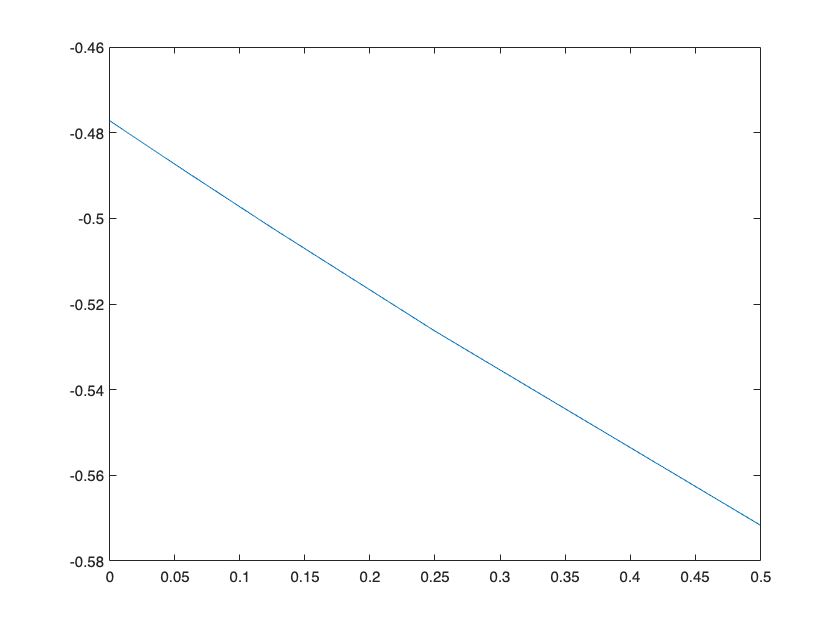

plot(taula(:, 1), log10(taula(:, 2)))

**Primera extrapolació, columna N_2**

T1(1) = 0;
T1(2:n) = (2*fp(2:n)-fp(1:n-1));
er2 = abs(T1-ve); er2(1) = 0;
taula1 = [h(1:n);fp;T1;er2]';
varNames = {'1/2^k','N_1 = f´(2)','N_2 = f´(2)','error'};
T = array2table(taula1,'VariableNames',varNames); disp(T)

      1/2^k       N_1 = f´(2)    N_2 = f´(2)      error   
    __________    ___________    ___________    __________

           0.5      0.26813              0               0
          0.25      0.29764        0.32715       0.0061861
         0.125      0.31462         0.3316       0.0017296
        0.0625      0.32375        0.33288      0.00045694
       0.03125      0.32848        0.33322      0.00011738
      0.015625      0.33089         0.3333      2.9742e-05
     0.0078125      0.33211        0.33333      7.4853e-06
     0.0039062      0.33272        0.33333      1.8776e-06
     0.0019531      0.33303        0.33333      4.7017e-07
    0.00097656      0.33318        0.33333      1.1764e-07
    0.00048828      0.33326        0.33333      2.9422e-08
    0.00024414      0.33329        0.33333       7.357e-09
    0.00012207      0.33331        0.

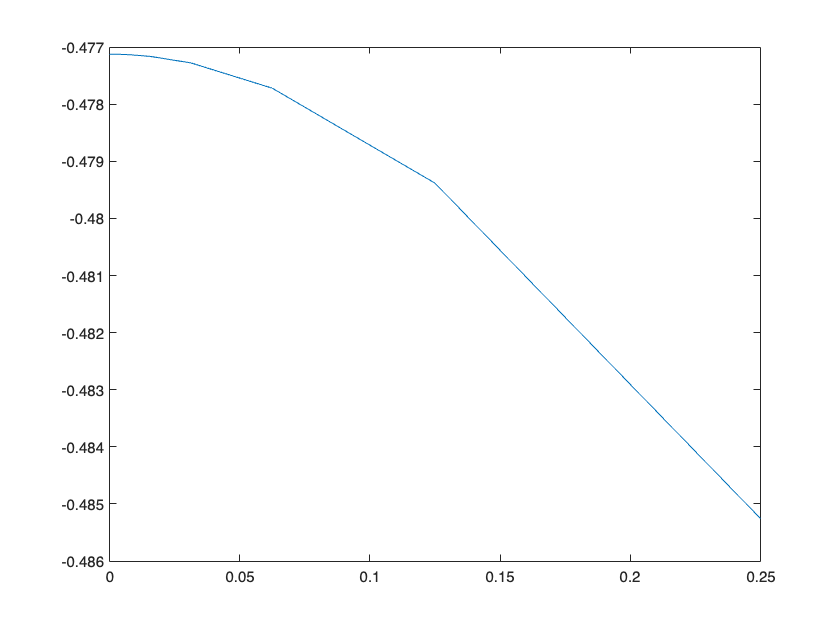

plot(taula1(:, 1), log10(taula1(:, 3)))

**Segona extrapolació, columna N_3**

T2(1:2) = 0;
T2(3:n) = (2^2*T1(3:n)-T1(2:n-1))/(2^2-1);
er3 = abs(T2-ve); er3(1:2) = 0;
taula2 = [h(1:n);fp;T1;T2;er3]';
varNames = {'1/2^k','N_1 = f´(2)','N_2 = f´(2)','N_3 = f´(2)','error'};
T = array2table(taula2,'VariableNames',varNames); disp(T)

      1/2^k       N_1 = f´(2)    N_2 = f´(2)    N_3 = f´(2)      error   
    __________    ___________    ___________    ___________    __________

           0.5      0.26813              0              0               0
          0.25      0.29764        0.32715              0               0
         0.125      0.31462         0.3316        0.33309      0.00024409
        0.0625      0.32375        0.33288         0.3333      3.2715e-05
       0.03125      0.32848        0.33322        0.33333      4.1946e-06
      0.015625      0.33089         0.3333        0.33333      5.2928e-07
     0.0078125      0.33211        0.33333        0.33333      6.6405e-08
     0.0039062      0.33272        0.33333        0.33333      8.3138e-09
     0.0019531      0.33303        0.33333        0.33333      1.0399e-09
    0.00097656 

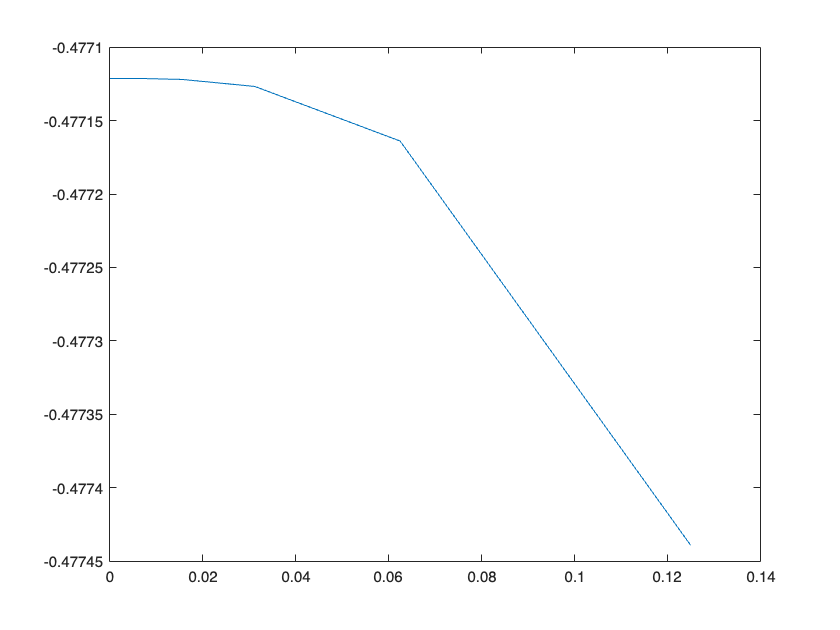

plot(taula2(:, 1), log10(taula2(:, 4)))

**Tercera extrapolació, columna N_4**

T3(1:2) = 0;
T3(3:n) = (2^3*T2(3:n)-T2(2:n-1))/(2^3-1);
er4 = abs(T3-ve); er4(1:3) = 0;
taula2 = [h(1:n);fp;T1;T2;T3;er4]';
varNames = {'1/2^k','N_1 = f´(2)','N_2 = f´(2)','N_3 = f´(2)','N_4 = f´(2)','error'};
T = array2table(taula2,'VariableNames',varNames); disp(T)

      1/2^k       N_1 = f´(2)    N_2 = f´(2)    N_3 = f´(2)    N_4 = f´(2)      error   
    __________    ___________    ___________    ___________    ___________    __________

           0.5      0.26813              0              0              0               0
          0.25      0.29764        0.32715              0              0               0
         0.125      0.31462         0.3316        0.33309        0.38067               0
        0.0625      0.32375        0.33288         0.3333        0.33333      2.5181e-06
       0.03125      0.32848        0.33322        0.33333        0.33333      1.2035e-07
      0.015625      0.33089         0.3333        0.33333        0.33333      5.6541e-09
     0.0078125      0.33211        0.33333        0.33333        0.33333      2.804

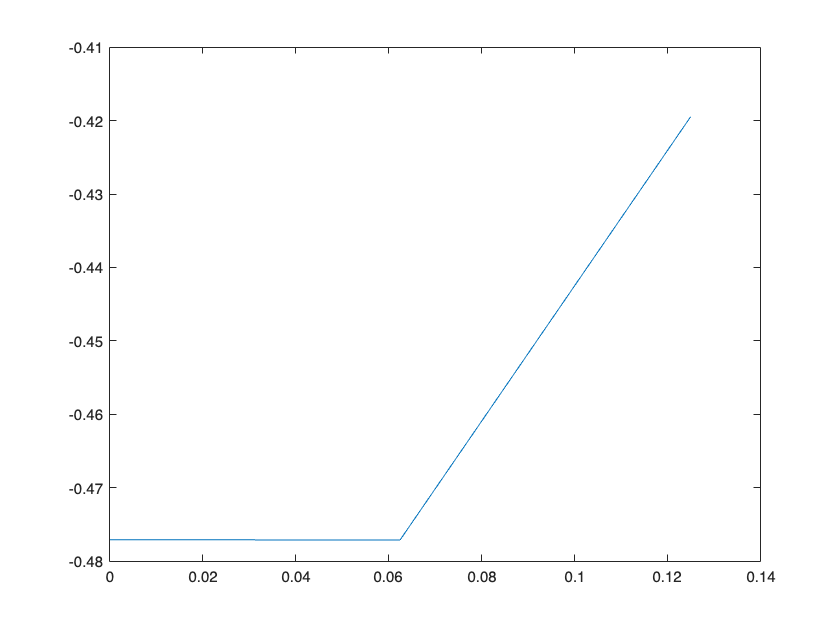

plot(taula2(:, 1), log10(taula2(:, 5)))

c) Respresentad las cifras decimales correctas en una gráfica con $k=1,2,3\dots, 15$ en el eje de abscisas.

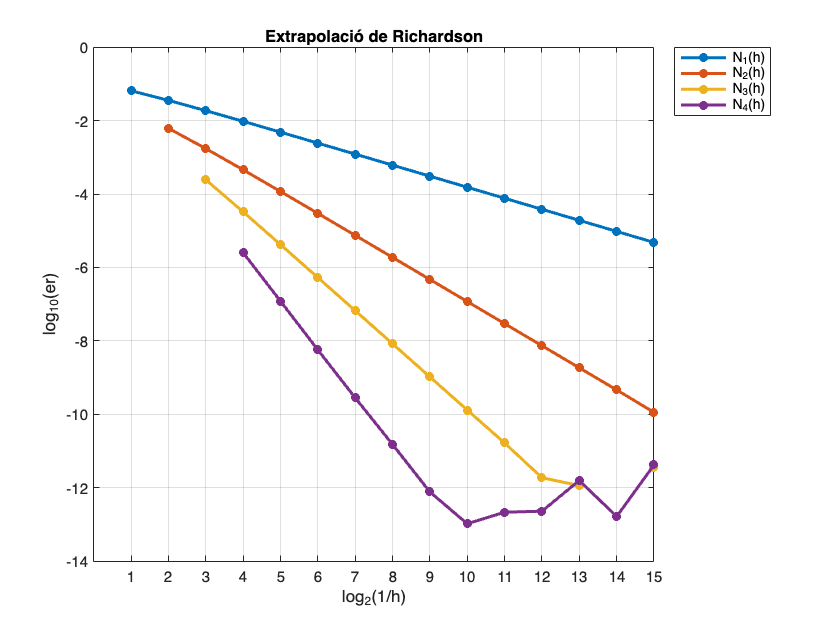

figure(1)
plot(hk,log10(er),'-*',hk,log10(er2),'-*',hk,log10(er3),'-*',hk,log10(er4),'-*','Linewidth',2); grid;
xlabel('log_{2}(1/h)');ylabel('log_{10}(er)'); title('Extrapolació de Richardson')
legend('N_1(h)','N_2(h)','N_3(h)','N_4(h)','Location','bestoutside'),xticks(1:n)

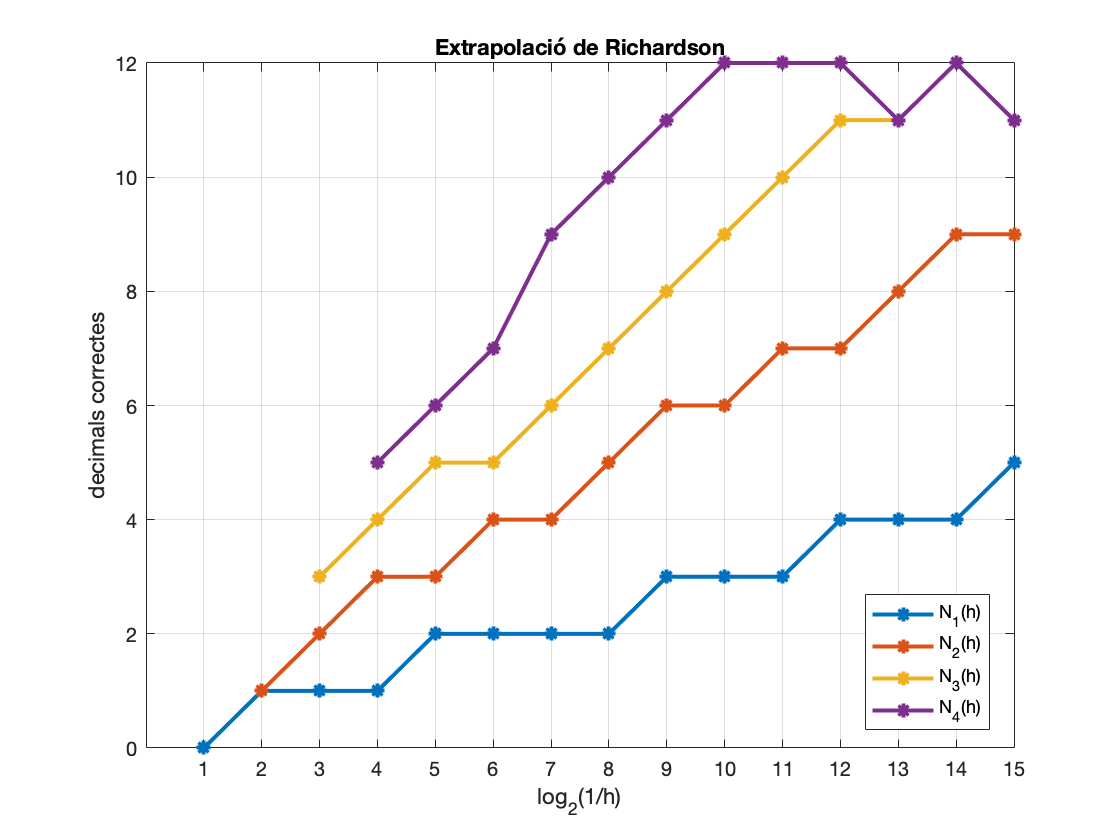


figure(2)
plot(hk,fix(-log10(2*er)),'-*',hk,fix(-log10(2*er2)),'-*',hk,fix(-log10(2*er3)),'-*',hk,fix(-log10(2*er4)),'-*','Linewidth',2); grid;
xlabel('log_{2}(1/h)');ylabel('decimals correctes'); title('Extrapolació de Richardson')
legend('N_1(h)','N_2(h)','N_3(h)','N_4(h)','Location','best'),xticks(1:n)

`Document preparat per Mª Àngela Grau Gotés (prof. responsable CN)`